# Figure 2F

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A009_data.mat'],'S','settings','allIF');

conditions = settings.conditions

conditions = 12×5 cell array
    {'siCtrl DMSO'  }    {[2]}    {[  2 3 4 5 6]}    {[1]}    {[0 0 0]}
    {'siCtrl DOX'   }    {[2]}    {[7 8 9 10 11]}    {[1]}    {[0 0 0]}
    {'siSkp2 DMSO'  }    {[3]}    {[  2 3 4 5 6]}    {[1]}    {[0 0 0]}
    {'siSkp2 DOX'   }    {[3]}    {[7 8 9 10 11]}    {[1]}    {[0 0 0]}
    {'siCCNA2 DMSO' }    {[4]}    {[  2 3 4 5 6]}    {[1]}    {[0 0 0]}
    {'siCCNA2 DOX'  }    {[4]}    {[7 8 9 10 11]}    {[1]}    {[0 0 0]}
    {'siCDC25a DMSO'}    {[5]}    {[  2 3 4 5 6]}    {[1]}    {[0 0 0]}
    {'siCDC25a DOX' }    {[5]}    {[7 8 9 10 11]}    {[1]}    {[0 0 0]}
    {'siCDC25b DMSO'}    {[6]}    {[  2 3 4 5 6]}    {[1]}    {[0 0 0]}
    {'siCDC25b DOX' }    {[6]}    {[7 8 9 10 11]}    {[1]}    {[0 0 0]}
    {'siCDC25c DMSO'}    {[7]}    {[  2 3 4 5 6]}    {[1]}    {[0 0 0]}
    {'siCDC25c DOX' }    {[7]}    {[7 8 9 10 11]}    {[1]}    {[0 0 0]}

framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    apcGate = false(length(dat.POI(:,2)),1);
    apcGateAll = false(length(dat.POI(:,2)),1); 
     crlGate = false(length(dat.POI(:,3)),1);

    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .1;
        end
       
        if dat.POI(n,3) + round(4*framesPerHr) <= numFrames 
            crlGate(n) = dat.crlNormAct(n,dat.POI(n,3) + round(4* framesPerHr)) < .5 ;
        end

    end
    S(i).apcExpressGate = apcExpressGate;
        S(i).apcGate = apcGate;
S(i).apcGateAll = apcGateAll;

   S(i).crlGate = crlGate;


end

numcell = 4979

numcell = 6352

numcell = 4936

numcell = 4721

numcell = 6234

numcell = 3260

numcell = 4693

numcell = 3342

numcell = 6479

numcell = 3328

numcell = 6539

numcell = 6529

numcell = 181

numcell = 4810

numcell = 82

numcell = 1677

numcell = 133

numcell = 3050

numcell = 6221

numcell = 1574

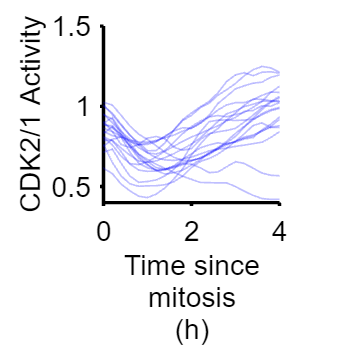

numcell = 4654

numcell = 147

numcell = 4723

numcell = 6295

numcell = 1486

numcell = 3119

numcell = 138

numcell = 1523

numcell = 1419

numcell = 1594

numcell = 3215

numcell = 105

numcell = 4581

numcell = 3024

numcell = 4796

numcell = 4629

numcell = 3169

numcell = 6276

numcell = 54

numcell = 4698

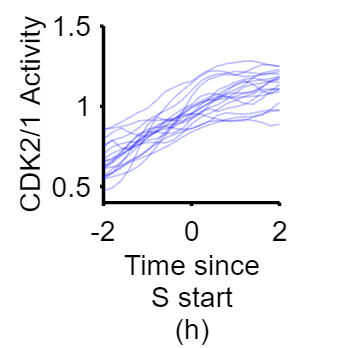

conds=[1];
poiAlign = [ 1 3];
alignNames = {'mitosis','S start'};
xlimits = {[0 4],[-2 2],[-6 8]};
for p = 1:length(poiAlign)
 figure('units','inches','position',[0 0 4 4]), hold on
    for i=1:length(conds)
      if p==1
        inds = ~isnan(S(conds(i)).POI(:,poiAlign(p)))&...
           S(conds(i)).goodCdk &...
           S(conds(i)).POI(:,1)>2 & S(conds(i)).POI(:,1)<50 &...
           S(conds(i)).apcExpressGate &...
          (S(conds(i)).traceStats(:,2)- S(conds(i)).traceStats(:,1)>30) & S(conds(i)).crlGate;
      else 
           inds = ~isnan(S(conds(i)).POI(:,poiAlign(p)))&...
           S(conds(i)).goodCdk &...
           S(conds(i)).POI(:,1)>00 & S(conds(i)).POI(:,1)<30 &...
           S(conds(i)).apcExpressGate &...
          (S(conds(i)).traceStats(:,2)- S(conds(i)).traceStats(:,1)>30) &...
          S(conds(i)).crlGate&((S(conds(i)).POI(:,3)-S(conds(i)).POI(:,1)>20));
      end 
        cells = find(inds);
        for numcell = randsample(cells,min([20 length(cells)]))'
            numcell
            timeAligned = xTime-S(conds(i)).POI(numcell,poiAlign(p))/framesPerHr;
            align_val = S(conds(i)).POI(numcell,poiAlign(p));
    
            start = S(conds(i)).POI(numcell,1) + 2;
           
            subplot(1,length(conds),i),hold on
            patchline(timeAligned,nansmooth(S(conds(i)).cdk(numcell,:),4),...
                'edgecolor',[0 0 1],'linewidth',1,'edgealpha',0.25);
            ylabel('CDK2/1 Activity');
            ylim([.4 1.5]);
            yticks([.5:.5:1.5])
            xlim(xlimits{p});
            xlabel(['Time since' alignNames(p) '(h)']);
            axis square
            set(gca,'linewidth',2,'fontsize',17)
   
        end
    end
      % print_pdf(['fig_2f',num2str(p),'.pdf'])
end